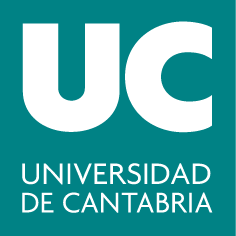

*Dpto. Matemática Aplicada y Ciencias de la Computación*

**Métodos Matemáticos en la Ingeniería**

**Bloque II: Métodos Numéricos**

# **3-2. Integración**

## Introducción

El concepto de integral definida está íntimamente relacionado con el concepto de área bajo una función en un determinado intervalo: 

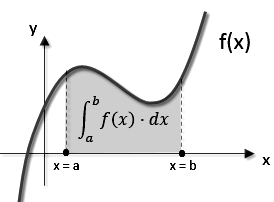

Si $$f$$ se define en el intervalo cerrado $$[a,b]$$, la **integral definida** se define como límite de las sumas de Riemann:

	
$$$$\int_{a}^{b}f(x) dx =  \lim\limits_{||\Delta x||\to 0} \sum_{i=1}^{n} f(c_i)\Delta x_i.$$$$


Repaso del cálculo simbólico ([`Symbolic Math Toolbox`](https://es.mathworks.com/help/symbolic/sym.int.html)):

## 3.2. Fórmulas de  Newton-Cotes

Las fórmulas de Newton-Cotes se basan en la estrategia de reemplazar una función complicada o datos tabulados por un polinomio de aproximación que es fácil de integrar:


$$$$\int_a^b f(x)dx \approx \int_a^b p_n(x)dx,$$$$


donde $$p_n(x) = a_0 + a_1x + \ldots + a_n x^n$$ - un polinomio de grado $ $n$$.

#### Regla del trapecio

[Polinomio de grado 1]: Una línea recta se puede representar como


$$$$p_1(x) = f(a) + \frac{f(b)-f(a)}{b-a}(x-a)$$$$


Sustituimos en la integral:


$$$$I = \int_a^b f(x)dx \approx \int_a^b \left[ f(a) + \frac{f(b)-f(a)}{b-a}(x-a) \right]dx  =  (b-a)\frac{f(b) + f(a)}{2}$$$$


**Regla del trapecio: **$$$I = \int_a^b f(x)dx \approx (b-a)\frac{f(b) + f(a)}{2}$$$

 Geométricamente, la regla del trapecio es equivalente a aproximar el área del trapecio bajo la línea recta que une $$f(a)$$ y $$f(b)$$:

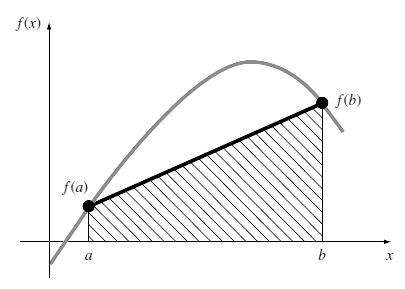

Área del trapecio: altura por el promedio de las bases. 

La integral aproximada: $$$I \approx \text{ancho} \times  \text{altura promedio} = (b-a) \times \frac{f(b) + f(a)}{2}$$$

**Ejercicio 3.11 **: Integra numéricamente $$$f(x) = 0.2 + 25x - 200x^2 + 675x^3 - 900x^4 + 400x^5$$$ desde $$a = 0$ $hasta $$b = 0.8$$.

clearvars
close all
f = @(x) 0.2 + 25*x - 200*x.^2 + 675*x.^3 - 900*x.^4 + 400*x.^5;
a = 0; b = 0.8;
I_trapecio = (b-a)*(f(a) + f(b))/2

Para calcular el valor "exacto" de la integral utilizamos el cálculo simbólico:

syms x
fs(x) = 0.2 + 25*x - 200*x^2 + 675*x^3 - 900*x^4 + 400*x^5; 
I_exacto = double(int(fs, a,b));
fprintf("Integral: %f\n", I_exacto)

Calculamos el error:

Er_abs = abs(I_exacto - I_trapecio);
Er_rel = Er_abs/abs(I_exacto)*100;
fprintf("Regla del trapecio:\nError absoluto: %f,\nError relativo: %.1f%%\n",Er_abs,Er_rel)

Para entender por qué el error es tan grande, representamos la función y la recta de interpolación lineal $$$p_1(x) = f(a) + \frac{f(b)-f(a)}{b-a}(x-a)$$$ en el intervalo $[a,b]$:

p1 = @(x) f(a) + (f(b) - f(a)) / (b-a)*(x-a);
x = linspace(a,b);
fx = f(x);
p1x = p1(x);
area(x,fx,'FaceAlpha',0.5)
hold on
area(x,p1x,'FaceAlpha',0.5)
legend('Área', 'Aproximación')
grid on

**Error de la regla del trapecio**

Introducimos la función: $$$g(h) = \frac{h}{2} \left(f(a) + f(a+h)\right) - \int_a^{a+h} f(x)dx$$$

Sus derivadas:


$$$g'(h) = \frac{1}{2}\left(f(a) - f(a+h)\right) + \frac{h}{2}f'(a+h)$$$



$$$g''(h) = \frac{h}{2} f''(a+h)$$$


Existe $$\xi$$ tal que$ $|f''(x)| \leq f''(\xi)$$, entonces $$$|g''(h)| \leq \frac{f''(\xi) h}{2}$$$.

Como $$$g'(0) = 0, \quad g(0) = 0,$$$ tenemos


$$$$g'(h) = \int_0^h g''(x)dx, \quad g = \int_0^h g'(x)dx$$$$


Entonces,

$ $|g'(h)| \leq \frac{f''(\xi)h^2}{4}$$, $$|g(h)| \leq \frac{f''(\xi)h^3}{12}$$,

y, por lo tanto,


$$$$g(b-a) = (b-a) \frac{f(b)+f(a)}{2} - \int_a^b f(x) dx \leq \frac{f''(\xi)(b-a)^3}{12}$$$$


La regla del trapecio: $$$\int_a^b f(x) dx = (b-a) \frac{f(b)+f(a)}{2} -  \frac{f''(\xi)(b-a)^3}{12}$$$

#### Reglas de Simpson

La regla de Simpson (nombrada así por Thomas Simpson) halla la integral aproximada de una función mediante un polinomio de segundo o tercer grado.

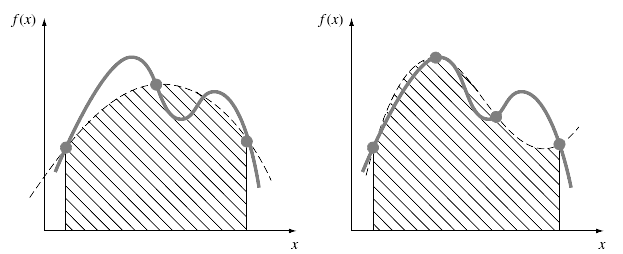

- Regla de Simpson 1/3 ( polinomio de segundo grado, 3 puntos equidistantes)

- Regla de Simpson 3/8 ( polinomio de tercer grado, 4 puntos equidistantes)

**Regla de Simpson 1/3**


$$$$I = \int_a^b f(x) dx \approx \int_a^b p_2(x)dx$$$$


Tres nodos: $h = \frac{b-a}{2}, \;x_0 = a, \;x_1 = a+h, \;x_2 = a+2h = b$

Valores: $f(x_0) = f_0, \; f(x_1) = f_1, \; f(x_2) = f_2. \; $

Polinomio de Lagrange de segundo grado:


$$$$p_2(x) = \frac{(x-x_1)(x-x_2)}{(x_0 - x_1)(x_0 - x_2)}f_0+ \frac{(x-x_0)(x-x_2)}{(x_1 - x_0)(x_1 - x_2)}f_1 + \frac{(x-x_0)(x-x_0)}{(x_2 - x_0)(x_2 - x_1)}f_2$$$$


Como $x_0 - x_1 = -h, x_0 - x_2 = -2h,  $ Sustituimos en el integrando:


$$$$\int_{x_0}^{x_2} \left[ \frac{(x-x_1)(x-x_2)}{2h^2}f_0 - \frac{(x-x_0)(x-x_2)}{h^2}f_1 + \frac{(x-x_0)(x-x_0)}{2h^2}f_2 \right]dx$$$$


Después de la integración y de las manipulaciones algebraicas, se obtiene la siguiente fórmula:

Regla de Simpson 1/3: $
$$I = \int_a^b f(x) dx \approx \frac{h}{3}\left[ f_0 + 4f_1 + f_2 \right]$$$

**Ejercicio 3.11**: Integra numéricamente $$$f(x) = 0.2 + 25x - 200x^2 + 675x^3 - 900x^4 + 400x^5$$$ desde $$a = 0$ $hasta $$b = 0.8$$.

clear all
close all
f = @(x) 0.2 + 25*x - 200*x.^2 + 675*x.^3 - 900*x.^4 + 400*x.^5;
a = 0; b = 0.8;
h = (b-a)/2;
% Definimos los nodos y calculamos los valores de la función f(x) en estos
% nodos:
x = a:h:b;
fx = f(x);
% Aplicamos la fórmula de Simpson 1/3:
I_simpson = h/3*(fx(1) + 4*fx(2) + fx(3))

Calculamos el error y representamos ambas áreas:

I_exacto = 1.640533;
Er_abs = abs(I_exacto - I_simpson);
Er_rel = Er_abs/abs(I_exacto)*100;
fprintf("Regla de Simpson 1/3:\nError absoluto: %f,\nError relativo: %.1f%%\n",Er_abs,Er_rel)
p2 = @(t) (t-x(2)).*(t-x(3))/(2*h^2)*fx(1) -...
          (t-x(1)).*(t-x(3))/(h^2)*fx(2)+...
          (t-x(1)).*(t-x(2))/(2*h^2)*fx(3);
x = linspace(a,b);
fx = f(x);
p2x = p2(x);
area(x,fx,'FaceAlpha',0.5)
hold on
area(x,p2x,'FaceAlpha',0.5)
legend('Área', 'Aproximación')
grid on

**Error de la regla de Simpson 1/3**

Se puede demostrar que la aplicación a un solo segmento de la regla de Simpson 1/3 tiene un error de truncamiento de


$$$$E_t = -\frac{h^5}{90}f^{(4)}(\xi), \quad h= \frac{b-a}{2}$$$$


Así, la regla de Simpson 1/3 es más precisa que la regla del trapecio. Además, da resultados exactos para polinomios cúbicos aun cuando se obtenga de una parábola.

**Ejercicio 3.12**: Integra numéricamente $$$f(x) = x^3-3x+1$$$ desde $$a = 0$ $hasta $$b = 1$$.

clear all
close all
f = @(x) x.^3 - 3*x+1;
a = 0; b = 1.25;
% Regla de Simpson 1/3:
h = (b-a)/2;
x = a:h:b;
fx = f(x);
I_simpson = h/3*(fx(1) + 4*fx(2) + fx(3))

Calculamos el valor exacto:

syms x
fs(x) = x.^3 - 3*x+1;
I_exacto = double(int(fs, a,b));
fprintf("Integral: %f\n", I_exacto)

Calculamos el error:

Er_abs = abs(I_exacto - I_simpson);
Er_rel = Er_abs/abs(I_exacto)*100;
fprintf("Regla de Simpson 1/3:\nError absoluto: %f,\nError relativo: %.1f%%\n",Er_abs,Er_rel)

**Ejercicio 3.13 **Utiliza la regla de Simpson 1/3 para aproximar la  integral entre 0 y 1 de la función$ $$f(x) = |\sin (2\pi x)|$$$ Compara con el resultado exacto, y explica los resultados. ¿Cómo se puede resolver este problema?

% escribe  el código aquí





**Regla de Simpson 3/8**

De manera similar a la obtención de la regla del trapecio y Simpson 1/3, es posible ajustar un polinomio de Lagrange de tercer grado a cuatro puntos e integrarlo:


$$$$I = \int_a^b f(x) dx \approx \int_a^b p_3(x)dx$$$$


Cuatro nodos:  $$h = \frac{b-a}{3}$, $x_0 = a$, $x_1 = a+h$, $x_2 = a+2h$, $x_3 = b$$

Valores: $f(x_i) = f_i, i = 0,\ldots,3.$

Regla de Simpson 3/8:$$$I = \int_a^b f(x) dx = \frac{3h}{8} \left[f_0 + 3f_1 + 3f_2 + f_3\right] -\frac{3h^5}{80}f^{(4)}(\xi)$$$

**Ejemplo**: Implementa la regla de Simpson 3/8 para integrar numéricamente $$$f(x) = 0.2 + 25x - 200x^2 + 675x^3 - 900x^4 + 400x^5$$$ desde $$a = 0$ $hasta $$b = 0.8$$. Calcula el error relativo. 

clear all
close all
f = @(x) 0.2 + 25*x - 200*x.^2 + 675*x.^3 - 900*x.^4 + 400*x.^5;
a = 0; b = 0.8;
h = (b-a)/2;

% escribe aquí el código:






Para comprobar los resultados:

regla = 1;
I = newton_cotes(f, a,b, regla);

Ir a "newton_cotes"

En la práctica de la ingeniería, las fórmulas de grado superior (es decir, con más de cuatro puntos) son poco utilizadas. Las reglas de Simpson bastan para la mayoría de las aplicaciones. La exactitud se puede mejorar al usar las fórmulas compuestas.

#### **Fórmulas compuestas**

Una forma de mejorar la precisión de la regla del trapecio consiste en dividir el intervalo de integración de a a b en varios segmentos, y aplicar el método a cada uno de ellos: 

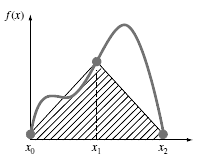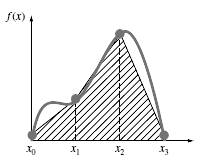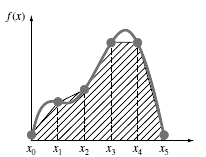

Las áreas de los segmentos se suman después para obtener la integral en todo el intervalo. Las ecuaciones resultantes se llaman fórmulas de integración, de aplicación múltiple o **compuestas**.

Hay $$n + 1$$ puntos igualmente espaciados $$(x_0, x_1, x_2, \ldots, x_n)$$. En consecuencia, existen$ $n$ $segmentos del mismo ancho $$h = \frac{b-a}{n}$$.

Si $$a$ y $b$$ se designan como $$x_0$$ y $$x_n$$, respectivamente, la integral completa se representará como


$$$$\int_a^b f(x) dx = \int_{x_0}^{x_1} f(x) dx + \int_{x_1}^{x_2} f(x) dx + \ldots + \int_{x_{n-1}}^{x_n} f(x) dx $$$$


Sustituyendo la regla del trapecio en cada integral se obtiene


$$$$\int_a^b f(x) dx \approx h \frac{f(x_0) + f(x_1)}{2} + h \frac{f(x_1) + f(x_2)}{2} + \ldots + h \frac{f(x_{n-1}) + f(x_n)}{2} $$$$


Agrupando términos, se obtiene la **Regla del trapecio compuesta**:


$$$$\int_a^b f(x) dx \approx \frac{h}{2} \left[f_0 + f_n+2 \sum_{i=1}^{n-1} f_i\right]$$$$


donde  $$h = \frac{b-a}{n}$, $x_i = a + ih$, $f(x_i) = f_i.$

**Ejercicio 3.14: **Implementa la regla del trapecio compuesta con $n= 2, 4, 8$ segmentos para integrar numéricamente  $$$f(x) = 0.2 + 25x - 200x^2 + 675x^3 - 900x^4 + 400x^5$$$ desde $$a = 0$ $hasta $$b = 0.8$$. Calcula el error relativo en cada caso.

clearvars
close all
f = @(x) 0.2 + 25*x - 200*x.^2 + 675*x.^3 - 900*x.^4 + 400*x.^5;
a = 0; b = 0.8;
I_exacto = 1.640533;
n = 2; % 4, 8

% escribe aquí el código





**Error de la regla del trapecio compuesta**

Se tiene un error con la regla del trapecio de aplicación múltiple al sumar los errores individuales de cada segmento, así


$$$$E_t = \frac{(b-a)^3}{12n^3} \sum_{i=1}^n f''(\xi),$$$$


donde $$f''(\xi)$$ es la segunda derivada en un punto $$\xi$$, localizado en el segmento $$i$$. Este resultado se simplifica al estimar la media o valor promedio de la segunda derivada en

todo el intervalo como $$$\bar{f}''(\xi) = \frac{1}{n} \sum_{i=1}^n f''(\xi)$$$

Por lo tanto, el error de la regla del trapecio compuesta es 


$$$$E_t = \frac{(b-a)^3}{12n^2} \bar{f}''(\xi)$$$$


Así, si se duplica el número de segmentos, el error de truncamiento se divide entre cuatro.

Si se requiere de alta exactitud, la regla del trapecio de múltiples segmentos exige un gran trabajo computacional. Puede ser muy importante cuando: se evalúan numerosas integrales, odonde la función misma es consumidora de tiempo en su evaluación.

**Regla de Simpson compuesta**

Así como en la regla del trapecio, la regla de Simpson se mejora al dividir el intervalo de integración en $n$ segmentos  ($n$ debe ser par) del tamaño $$$h= \frac{b-a}{n}$$$. La integral total se puede representar como


$$$$\int_a^b f(x) dx = \int_{x_0}^{x_2}f(x)dx + \ldots
+ \int_{x_{n-2}}^{x_n}f(x)dx$$$$


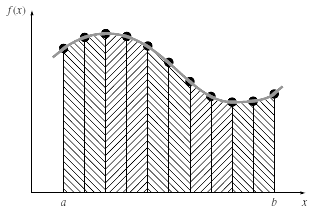

Al sustituir la regla de Simpson 1/3 en cada integral se obtiene la  **Regla de Simpson compuesta**:


$$$$\int_a^b f(x) dx \approx 2h \sum_{i=0}^{n-2} \frac{f_i +4f_{i+1}+f_{i+2}}{6} $$$$


Reordenando los términos se obtiene:


$$	$$\int_a^b f(x) dx \approx\frac{h}{3} \left( f_0 + 4 \sum_{i=1,3,5}^{n-1}f_i + 2 \sum_{j=2,4,6}^{n-2} f_j + f_n\right)$$$$


**Ejercicio 3.14: **Implementa la regla de Simpson compuesta con $n= 2, 4, 8$ segmentos para integrar numéricamente  $$$f(x) = 0.2 + 25x - 200x^2 + 675x^3 - 900x^4 + 400x^5$$$ desde $$a = 0$ $hasta $$b = 0.8$$. Calcula el error relativo en cada caso.

clear all
close all
f = @(x) 0.2 + 25*x - 200*x.^2 + 675*x.^3 - 900*x.^4 + 400*x.^5;
a = 0; b = 0.8;
I_exacto = 1.640533;
n = 2; % 4, 8

% escribe aquí el código





**Error de la regla de Simpson compuesta**

Error de la regla de Simpson: $$$E_t = -\frac{h^5}{90}f^{(4)}(\xi), \quad h= \frac{b-a}{2}$$$

Sumando los errores individuales de los segmentos y sacando el promedio de la derivada, el error estimado de la regla de Simpson compuesta se obtiene:


$$$$E_t = -\frac{(b-a)^5}{180n^4}\bar{f}^{(4)}$$$$


Una posible implementación de la regla de Simpson compuesta: 

#### Integración con MATLAB

La función `integral` en MATLAB evalúa la integral definida de una función en un intervalo $[a,b]$ utilizando métodos adaptativos de cuadratura. Es capaz de manejar funciones complejas, incluyendo aquellas que pueden tener singularidades en el intervalo de integración.

- `fun`: La función que se desea integrar. Puede ser un handle de función, una función anónima, o una función definida como una cadena de caracteres.

- `a`: El límite inferior del intervalo de integración.

- `b`: El límite superior del intervalo de integración.

La función `integral` permite especificar opciones adicionales mediante pares de nombre-valor:

- `'RelTol'`: Tolerancia relativa, por defecto es `1e-6`.

- `'AbsTol'`: Tolerancia absoluta, por defecto es `1e-10`.

**Ejemplo: **Utiliza la función integral  para integrar numéricamente  $$$f(x) = 0.2 + 25x - 200x^2 + 675x^3 - 900x^4 + 400x^5$$$ desde $$a = 0$ $hasta $$b = 0.8$$. 

clear all
close all
format long 
f = @(x) 0.2 + 25*x - 200*x.^2 + 675*x.^3 - 900*x.^4 + 400*x.^5;
a = 0; b = 0.8;
I_exacto = 1.640533;
I = integral(f,a,b,'AbsTol',1e-6);

## Bibliografía

- [Chapra S.C.; Canale R. (2015) Métodos Numéricos para Ingenieros. Ed. McGRaw-Hill](https://catalogo.unican.es/cgi-bin/abnetopac?TITN=436963) (Capítulos 21, 22)

- [Mathews J.H., Fink K.D. (2000) Métodos Numéricos con MATLAB. Ed. Prentice Hall](https://catalogo.unican.es/cgi-bin/abnetopac?TITN=163396) (Capítulo 7)

Funciones auxiliares

1. Fórmulas de Newton-Cotes:

function [I, Er] = newton_cotes(f, a,b, regla)
h = (b-a)/regla;
x = a:h:b;
fx = f(x);
switch regla
    case 1 % trapecio
        fprintf("Fórmula: h/2 * (f_0 + f_1)");
        I = h/2*sum(fx);
    case 2 % Simpson 1/3
        fprintf("Fórmula: h/3 * (f_0 + 4f_1 + f_2)");
        I = h/3 * (fx(1) + 4*fx(2) + fx(3));
    case 3 % Simpson 3/8
        fprintf("Fórmula: 3h/8 * (f_0 + 3f_1 + 3f_2 + f_3)");
        I = 3*h/8 * (fx(1) + 3*fx(2) + 3*fx(3) + fx(4));
    case 4 % Boole
        fprintf("Fórmula: 2h/45 * (7f_0 + 32f_1 + 12f_2 + 32f_3 + 7f_4)");
        I = 2*h/45 * (7*fx(1) + 32*fx(2)+ 12*fx(3) + 32*fx(4) + 7*fx(5));
end
fs = sym(f);
I_e = double(int(fs,a,b));
Er_rel2 = abs(I_e - I) / abs(I_e)*100;
fprintf("\nValor aproximado: %.8f\nValor exacto:     %.8f\nError relativo:   %.4f%%",I,I_e,Er_rel2)
end